%% ===================== 熵特征处理与可视化（SE + PE + COPPS） =====================
% 功能：
%   1. 加载三个熵特征图（Features_SE, Features_PE, Features_COPPS）和标签（Features_Labelscopps）
%   2. 构建三通道输入 X（通道顺序：SE, PE, COPPS）
%   3. 自适应缩放（若尺寸过小则放大至 8×8）
%   4. 划分训练/验证集并标准化
%   5. 绘制每个类别的平均 RGB 特征图（论文风格）
%
% 使用前提：工作区必须存在变量：
%   Features_SE, Features_PE, Features_COPPS, Features_Labelscopps（categorical类型）
% ========================================================================

clc; close all; warning('off'); rng(1);

%% --------------------- 1. 检查必要变量是否存在 -------------------------
if ~exist('Features_SE','var') || ~exist('Features_PE','var') || ~exist('Features_COPPS','var')
    error('缺少特征变量，请加载 Features_SE, Features_PE, Features_COPPS');
end
if ~exist('Features_Labelscopps','var') || isempty(Features_Labelscopps)
    error('缺少标签变量 Features_Labelscopps（应为 categorical 类型）');
end
if ~iscategorical(Features_Labelscopps)
    Features_Labelscopps = categorical(Features_Labelscopps);
end

% 获取维度信息（以 Features_SE 为准，假设三者尺寸一致）
N = size(Features_SE, 1);
H = size(Features_SE, 2);
W = size(Features_SE, 3);
fprintf('原始输入尺寸: %d × %d, 样本数: %d\n', H, W, N);

原始输入尺寸: 8 × 8, 样本数: 1548



classNames = categories(Features_Labelscopps);
numClasses = numel(classNames);

%% --------------------- 2. 构建三通道特征图 X ----------------------------
% 通道顺序：1=SE, 2=PE, 3=COPPS
% 若尺寸过小，自动放大至 8×8 以适应后续池化操作

if H < 8 || W < 8
    warning('输入尺寸 %dx%d 过小，自动缩放至 8x8', H, W);
    targetSize = [8, 8];
    X = zeros(8, 8, 3, N, 'single');
    for i = 1:N
        X(:,:,1,i) = imresize(squeeze(Features_SE(i,:,:)), targetSize);
        X(:,:,2,i) = imresize(squeeze(Features_PE(i,:,:)), targetSize);
        X(:,:,3,i) = imresize(squeeze(Features_COPPS(i,:,:)), targetSize);
    end
    H = 8; W = 8;
else
    X = zeros(H, W, 3, N, 'single');
    for i = 1:N
        X(:,:,1,i) = squeeze(Features_SE(i,:,:));
        X(:,:,2,i) = squeeze(Features_PE(i,:,:));
        X(:,:,3,i) = squeeze(Features_COPPS(i,:,:));
    end
end

% 保存原始特征（用于热图，未经标准化）
X_original = X; 

%% --------------------- 3. 划分数据集与标准化 ----------------------------
% 使用 hold-out 划分（30% 验证）
cv = cvpartition(Features_Labelscopps, 'Holdout', 0.3);
XTrain = X(:,:,:,training(cv)); YTrain = Features_Labelscopps(training(cv));
XVal   = X(:,:,:,test(cv));    YVal   = Features_Labelscopps(test(cv));

% 按训练集均值和标准差标准化（每个通道独立）
mu = zeros(1,1,3);
sigma = zeros(1,1,3);
for c = 1:3
    mu(c) = mean(XTrain(:,:,c,:), 'all');
    sigma(c) = std(XTrain(:,:,c,:), 0, 'all');
    XTrain(:,:,c,:) = (XTrain(:,:,c,:) - mu(c)) ./ (sigma(c) + 1e-6);
    XVal(:,:,c,:)   = (XVal(:,:,c,:)   - mu(c)) ./ (sigma(c) + 1e-6);
end
fprintf('标准化完成。\n');

标准化完成。



%% --------------------- 4. 绘制每个类别的平均 RGB 特征图（每类单独显示+保存） -----------------
fprintf('生成平均 RGB 特征图...\n');

生成平均 RGB 特征图...



%======================================================================
% 保存路径：当前MATLAB工作目录/RGB_FeatureMaps
%======================================================================
saveFolder = fullfile(pwd,'22RGB_FeatureMaps');

if ~exist(saveFolder,'dir')
    mkdir(saveFolder);
end

fprintf('RGB特征图保存位置：\n%s\n\n', saveFolder);

RGB特征图保存位置：
D:\桌面\最新版江苏大学数据\2048+20W\江苏科技大学（JUST）回转支承数据集最终88 - 副本\22RGB_FeatureMaps



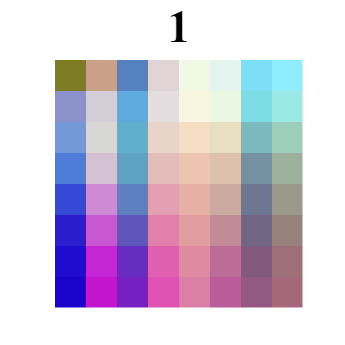

√ 已保存：D:\桌面\最新版江苏大学数据\2048+20W\江苏科技大学（JUST）回转支承数据集最终88 - 副本\22RGB_FeatureMaps\22_1.png


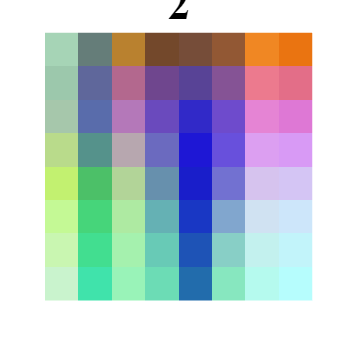

√ 已保存：D:\桌面\最新版江苏大学数据\2048+20W\江苏科技大学（JUST）回转支承数据集最终88 - 副本\22RGB_FeatureMaps\22_2.png


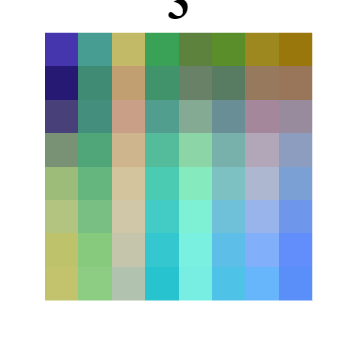

√ 已保存：D:\桌面\最新版江苏大学数据\2048+20W\江苏科技大学（JUST）回转支承数据集最终88 - 副本\22RGB_FeatureMaps\22_3.png


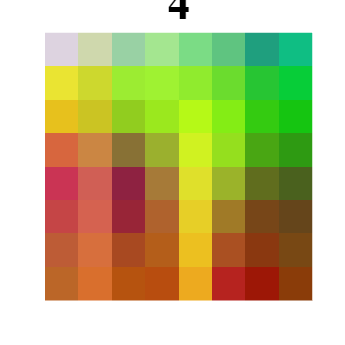

√ 已保存：D:\桌面\最新版江苏大学数据\2048+20W\江苏科技大学（JUST）回转支承数据集最终88 - 副本\22RGB_FeatureMaps\22_4.png



for cls = 1:numClasses

    %==================== 当前类别样本 ====================
    idx = (Features_Labelscopps == classNames{cls});

    if sum(idx)==0
        continue;
    end

    %==================== 求平均RGB图 ====================
    rgb = mean(X_original(:,:,:,idx),4);

    %==================== 三通道分别归一化 ====================
    for c = 1:3

        img = rgb(:,:,c);

        % 去最小值
        img = img - min(img(:));

        % 归一化
        img = img ./ (max(img(:)) + eps);

        % Gamma增强
        img = img.^0.8;

        % 轻微平滑
        img = imgaussfilt(img,0.5);

        rgb(:,:,c) = img;

    end

    %==================== 创建Figure ====================
    fig = figure(...
        'Color','w',...
        'Name',char(classNames{cls}),...
        'NumberTitle','off',...
        'Position',[300 200 650 650]);

    image(rgb);

    axis image
    axis off

    title(char(classNames{cls}),...
        'FontName','Times New Roman',...
        'FontWeight','bold',...
        'FontSize',22);

    drawnow;

    %==================== 保存图片 ====================
    fileName = fullfile(saveFolder,...
        sprintf('22_%s.png',char(classNames{cls})));

    try

        exportgraphics(fig,...
            fileName,...
            'Resolution',600,...
            'BackgroundColor','white');

    catch

        saveas(fig,fileName);

    end

    fprintf('√ 已保存：%s\n',fileName);

end


fprintf('\n=========================================\n');

fprintf('所有RGB平均特征图生成完成！\n');

所有RGB平均特征图生成完成！


fprintf('保存目录：\n%s\n',saveFolder);

保存目录：
D:\桌面\最新版江苏大学数据\2048+20W\江苏科技大学（JUST）回转支承数据集最终88 - 副本\22RGB_FeatureMaps


fprintf('=========================================\n');